*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 4 :Multi-User Multiple-Input Multiple-Output (MU-MIMO) in 5G Networks**

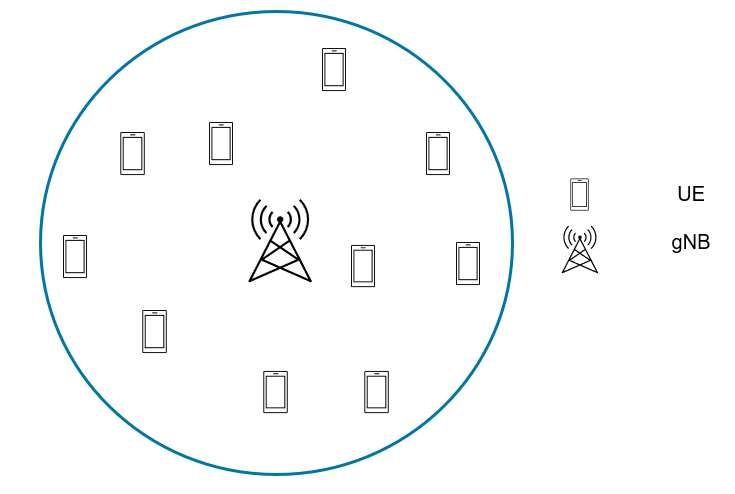

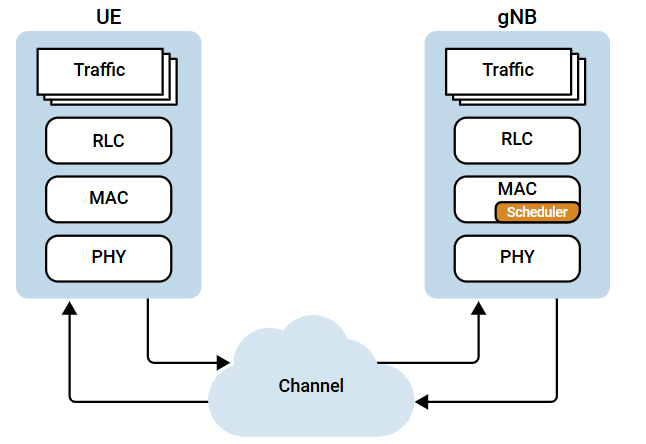

This exercise shows how to model an MU-MIMO scenario and integrate a custom resource-scheduling strategy into a 5G network model.

The goals are to:

- Explore MU-MIMO scenarios 

- Visualize network KPIs for MU-MIMO 

- Prioritize specific nodes during resource scheduling using a custom scheduling algorithm 

- Visualize and quantify the impact of the custom scheduler

#### Close any previously opened figures 

- Close all previous windows

- Reset the random number generator for reproducibility

all_figs = findall(0, 'type', 'figure');close(all_figs); 
rng("default")  

#### Initialize Variables and Wireless Network Simulator

- Initialize the Wireless Network Simulator

- Number of frames to simulate and simulation time in seconds 

- Set total number of UEs modeled 

- Launch the wireless network viewer to visualize the network during simulation

numFrameSimulation = 30; % Simulation time in terms of number of 10 ms frames
simulationTime = numFrameSimulation*0.01; % Simulation Time in seconds
numUEs = 10;
cellRadius =600;
networkSimulator = wirelessNetworkSimulator.init;
viewerObj = wirelessNetworkViewer(CanvasSize=[1200 1200]);

# Task 1/3: Create a 5G base station 

**Instructions to complete the task**

Use` nrGNB() `function to create a NR base station 

Store NR base station in a variable named "gNB"

Hint:type `doc nrGBN`  in command window and see the "Syntax" section.

Note : use the following values as arguments 

- "Position",gNBPosition

- "NumTransmitAntennas",numTxAntenna

- "NumReceiveAntennas",numRxAntenna

- "PHYModel",phyType

- "DuplexMode",duplexMode

- "Name","gNB"

phyType = "abstract-phy";
numTxAntenna = 32;
numRxAntenna = 32;
duplexMode = "TDD";
gNBPosition =  [0 0 10];

% <enter code below>
% gNB = 

addNodes(viewerObj,gNB,Type="gNB");

# Task #2/3 Configure the Scheduler at 5G base station 

**Description of the task**

MU-MIMO involves both the PHY and MAC layers.

- The **PHY layer** handles signal-processing tasks such as beamforming, precoding, channel estimation, and spatial stream separation to enable simultaneous transmission to multiple users. 

- The **MAC layer** manages user scheduling, grouping, resource allocation, and coordination of MU-MIMO transmissions.

These `muMIMOConfiguration` parameters are primarily MAC-layer / scheduler configuration parameters, although some are influenced by PHY-layer capabilities.

- `MaxNumUsersPaired`

- MAC layer

- Controls how many users can be scheduled together in an MU-MIMO transmission. 

- `MinNumRBs`

- MAC layer

- Related to resource block allocation and scheduling decisions. 

- `MaxNumLayers`

- Mostly PHY layer capability, but used by the MAC scheduler

- Refers to the maximum number of spatial layers/streams supported for MU-MIMO. 

- `MinSINR`

- Cross-layer parameter, but mainly used by the MAC scheduler

- SINR is a PHY-layer measurement, but the scheduler uses it to decide whether users are suitable for MU-MIMO pairing.

muMIMOConfiguration = struct(MaxNumUsersPaired=2, ...
    MinNumRBs=2, ...
    MaxNumLayers=8, ...
    MinSINR=10);
CSIMeasurementSignal = "SRS" ;

**Resource Allocation Type**

resourceAllocationType = 0;

**Custom Scheduler**

The New Radio (NR) scheduler is a key component of the 5G NR protocol stack. It is responsible for efficiently allocating radio resources to User Equipment (UE) nodes and resides in the MAC layer of the 5G protocol stack.

**Strategy Description**

Scheduling of High-Priority UE Nodes (Priority 1)

- The scheduler allocates a predefined fixed number of Resource Blocks (RBs) to each eligible high-priority UE. 

- If sufficient RBs are not available to serve all high-priority UEs with the required allocation, the scheduler selects and serves a random subset of high-priority UEs during that slot. 

Scheduling of Low-Priority UE Nodes (Priority 2)

- After allocating RBs to high-priority UEs, the scheduler distributes the remaining RBs equally among the low-priority UEs.

**Use cases **

- Industrial Automation: Prioritize real-time control traffic for robots and machines. 

- Public Safety Networks: Ensure reliable communication for emergency responders. 

- AI/ML-Based Scheduling: Dynamically optimize resource allocation based on network conditions.

RBsforHPUEs = 3; 
myScheduler = helperNRCustomSchedulingStrategy(NumRBHighPriority=RBsforHPUEs);
schedulerType = "RoundRobin";

**Instructions to complete the task**

Use configureScheduler() function 

Hint:type `doc configureScheduler`  in command window and see the "Syntax" section.

% Use the following arguments 

-      gNB

-     "Scheduler",schedulerType

-     "CSIMeasurementSignalDL",CSIMeasurementSignal

-     "ResourceAllocationType",resourceAllocationType

-     "MaxNumUsersPerTTI",numUEs

-     "MUMIMOConfigDL",muMIMOConfiguration

% <enter code below>


#### Create UE nodes. Specify the name and the position of each UE node

uePositions = [randi([-cellRadius/2 cellRadius/2],numUEs,2) ones(numUEs,1)];
ueNames = "ue-" + (1:size(uePositions,1));
UEs = nrUE(Position=uePositions,Name=ueNames);
addNodes(viewerObj,UEs,Type="UE");
showBoundary(viewerObj,Position=gNBPosition, BoundaryShape="Hexagon",Bounds=cellRadius, Name="Cell-1")

#### Connect the UE nodes to the gNB node and install traffic 

highPriorityUEs = [UEs(1),UEs(2),UEs(3), UEs(4),UEs(5)];
lowPriorityUEs  = [UEs(6),UEs(7),UEs(8), UEs(9),UEs(10)];
connectUE(gNB,highPriorityUEs, CustomContext=struct("Priority",1),FullBufferTraffic="on");
connectUE(gNB,lowPriorityUEs,CustomContext=struct("Priority",2), FullBufferTraffic="on");

####  Add UEs and gNBs to network simulator

addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)

#### Add channel Model 

- You can use CDL channel model for network simulation 

- You can use prebuilt channel models for various deployment scenarios defined in 3GPP TR 38.901.

- Control whether small-scale fading is applied to interfering signals in the channel model.

- You also use custom channel models 

channelModel = "CDL channel";
if strcmp(channelModel,"CDL channel")
    channelConfig = struct(DelayProfile="CDL-C",DelaySpread=1e-9,MaximumDopplerShift=1);
    channels = hNRCreateCDLChannels(channelConfig,gNB,UEs);
    channel = hNRCustomChannelModel(channels,struct(PHYModel=phyType));
    addChannelModel(networkSimulator,@channel.applyChannelModel)
else
    channel = h38901Channel(Scenario="UMa"); %#ok<*UNRCH>
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end


#### Enable visualizations

The displayed visualizations and metrics correspond to the selected cell of interest.

- Cell Performance Metrics – Shows key KPIs like throughput, fairness, and buffer status 

- RLC Metrics – Displays data transmitted at the RLC layer for each UE 

- BLER Metrics – Visualizes block error rates in uplink and downlink 

- Resource Grid Allocation – Shows time-frequency resource allocation and HARQ activity 

- Channel Quality – Displays MCS variations across time and frequency 

- Simulation Summary – Compares achieved performance with theoretical limits

simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation, gNB,UEs,LinkDirection="DL");
gridVisualizer = helperNRGridVisualizer(numFrameSimulation,gNB,UEs, ResourceGridVisualization=true,SchedulingLogger= simSchedulingLogger,MCSGridVisualization=false);
metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,RefreshRate=100,PlotSchedulerMetrics=true,PlotPhyMetrics=false,LinkDirection="DL");

# Task 3/3: Run the simulation

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use run() function to run the model    

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

% <enter code below>


*Copyright 2021-2024 The MathWorks, Inc.*